# Laboratorio di Automatica (Prova del 07 Luglio 2020)

Riccardo Antonello ([antonello@dei.unipd.it](mail:antonello@dei.unipd.it)) and Luca Schenato ([schenato@dei.unipd.it](mail:schenato@dei.unipd.it)) 

July 07, 2020

Dept. of Information Engineering, University of Padova

## Esercizio 3

In Fig. 3 è riportato lo schema di controllo di velocità a tempo discreto di un motore elettrico in corrente continua. Il motore ha funzione di trasferimento:


$$P(s)\,=\, \frac{\Theta(s)}{U_2(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


da ingresso in tensione $u\,\mathrm{[V]}$ ad uscita in posizione $\vartheta\,[\mathrm{rad}]$. Il controllore è un un regolatore proporzionale-derivativo in configurazione P-D (il termine derivativo D è posto sul ramo di retroazione, anzichè sul ramo diretto). I blocchi con funzioni di trasferimento $C_1(z)$ e $C_2(z)$ sono ottenuti discretizzando, *con il metodo di Eulero all'Indietro (Backward Euler)*, i seguenti modelli a tempo continuo:


$$C_1(s) =\frac{U_{C1}(s)}{E(s)} = K_P\,,
\qquad
C_2(s) = \frac{U_{C2}(s)}{\Omega(s)} = \frac{K_D s}{T_L s + 1}
\qquad\text{dove}\quad
K_P = 0.472\,,\quad
K_D=0.016\,,\quad
T_L=0.004$$


Il controllore include anche un compensatore in feedforward con funzione di trasferimento:


$$F(z) = \frac{U_F(z)}{\Omega^*(z)}=\frac{1}{k_m}$$


Il blocco con funzione di trasferimento $H(z)$ è un filtro "derivatore reale" utilizzato per ricavare una stima $\omega\,\mathrm{[rad/s]$ della velocità del motore a partire dalla misura di posizione $\vartheta\,[\mathrm{rad}]$; è ottenuto discretizzando, *con il metodo di Eulero all'Indietro (Backward Euler)*, il seguente filtro a tempo continuo:


$$H(s) = \frac{\Omega(s)}{\Theta(s)} = \frac{\omega_c^2\,s}{s^2 + 2 \delta \omega_c s + \omega_c^2}
\quad\text{con}\quad
\omega_c = 2 \pi\,5\,\mathrm{rad/s},\,\quad
\delta=\frac{1}{\sqrt{2}}$$


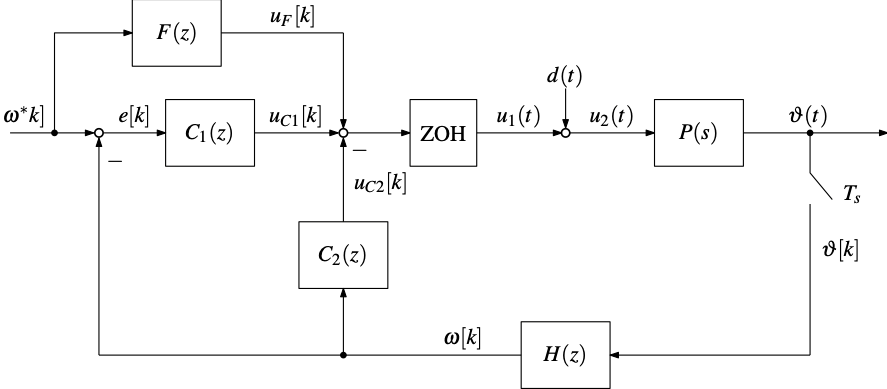

**Figura 3**: Sistema di controllo di velocità a tempo discreto.

Considerando un tempo di campionamento $T_s = 0.01\,\mathrm{s}$, si svolgano i seguenti punti: 

1) Realizzare uno schema Simulink del sistema di controllo di Fig. 3. Si assuma che:

- la tensione $u_1(t)$ sia fornita da un DAC (digital-to-analog converter) a 10 bit e range d uscita pari a $\pm\,10\,V$.

- la misura di posizione $\vartheta[k]$ sia fornita da un encoder con risoluzione pari a $2000\,\mathrm{ppr}$ (*pulses-per-rotation*, ovvero impulsi-per-giro).

Nota: per simulare sia il campionatore che lo Zero-Order Holder (ZOH), si faccia ricorso al blocco `Discrete `$\rightarrow$` Zero-Order Hold` della libreria di blocchi del Simulink.

*Soluzione*.

%   conversion gains
rads2rpm = 60/2/pi;
rpm2rads = 2*pi/60;

%   sampling time
Ts = 0.01;

%   motor tf
km = 5.2;
Tm = 0.03;
numP = km;
denP = [Tm, 1, 0];

%   speed filter tf
z = tf('z', Ts);
s = (z-1)/Ts/z;

wc = 2*pi*5;
d = 1/sqrt(2);
sysH = minreal( wc^2*s/(s^2 + 2*d*wc*s + wc^2) );
[numH, denH] = tfdata(sysH, 'v');
zpk(sysH)


ans =
 
      6.3964 z (z-1)
  -----------------------
  (z^2 - 1.584z + 0.6481)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.




%   P-D controller tf
Kp = 0.472;
Kd = 0.016;
TL = 0.004;

numC1 = Kp;
denC1 = 1;

sysC2 = minreal( Kd*s/(TL*s + 1) );
[numC2, denC2] = tfdata(sysC2, 'v');
zpk(sysC2)


ans =
 
  1.1429 (z-1)
  ------------
   (z-0.2857)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.




%   feedforward gain
kff = 1/km;

%   open Simulink model
open_system('ex3_sim1')

2) Simulare la risposta del sistema di controllo con un riferimento di velocità $\omega^*$ a gradino di ampiezza $A_r= 250\,\mathrm{rpm}$ applicato in $t_r = 0\,\mathrm{s}$, e un disturbo $d$ a gradino di ampiezza $A_d = 5\,\mathrm{V}$, applicato in $t_d = 1\,\mathrm{s}$. Si imposti un tempo finale di simulazione adeguato (es. $2\,\mathrm{s}$).

*Soluzione*.

%    set reference params (amplitude & start time)
Ar = 250*rpm2rads;  t0r = 0;  

%    set disturbance params (amplitude & start time)
Ad = 5;  t0d = 1;  

%    set simulation params
set_param('ex3_sim1', 'SolverType', 'Variable-step', ...
    'Solver', 'ode45', 'MaxStep', '0.001', 'StopTime','2');

%    run simulation
sim('ex3_sim1');

3)  Con riferimento alla simulazione eseguita al punto 2, mostrare in una figura MATLAB gli andamenti dei seguenti segnali: 	

- plot 1: velocità misurata $\omega[k]$ e riferimento $\omega^*[k]$, entrambi espressi in $[\mathrm{rpm}]$.

- plot 2: errore di inseguimento $e[k]$, espresso in $[\mathrm{rpm}]$.

- plot 3: comando di tensione $u_1(t)$ in $[V]$.

Verificare che il compensatore in feedforward garantisce inseguimento perfetto di riferimenti costanti, ma solo in *condizioni nominali*, ovvero in assenza di incertezze di modello e disturbi.

*Soluzione*.

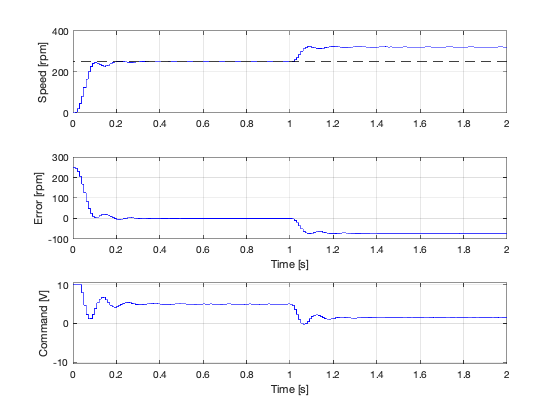

%   extract signas
t = simres.time;
w_meas = simres.signals(1).values(:,1);
w_ref = simres.signals(1).values(:,2);
e = simres.signals(2).values;
u1 = simres.signals(3).values;

%   plot results
figure;
subplot(3,1,1);
stairs(t, w_meas, 'b');
hold on;
stairs(t, w_ref, 'k--');
grid on;
ylabel('Speed [rpm]');

subplot(3,1,2);
stairs(t, e, 'b');
grid on;
ylabel('Error [rpm]');
xlabel('Time [s]');
ylim([-100, 300]);

subplot(3,1,3);
stairs(t, u1, 'b');
grid on;
ylim([-10.5, 10.5]);
ylabel('Command [V]');
xlabel('Time [s]');

4) Si consideri ora un controllore di tipo PI-D, in cui $C_1(z)$ in Fig. 3 viene ottenuto discretizzando, *con il metodo di Eulero all'Indietro (Backward Euler)*, il seguente controllore PI a tempo continuo


$$C_1(s) =\frac{U_{C1}(s)}{E(s)} = \frac{K_P\,s + K_I}{s}\,,
\qquad\text{dove}\quad
K_P = 0.472\,,\quad
K_I = 3.0$$


mentre $C_2(z)$ rimane identico a quello utilizzato nei punti precedenti. Si supponga inoltre assente l'azione di compensazione in feedforward, ovvero $F(z)=0$. 

Ripetere i punti 2 e 3 con il nuovo controllore PI-D. Verificare che l'azione integrale nel controllore assicura inseguimento perfetto di riferimenti costanti, anche in condizioni non nominali (inseguimento perfetto "robusto").

Soluzione.

%   PI-D controller tf
Kp = 0.472;
Ki = 3.0;
Kd = 0.016;
TL = 0.004;

sysC1 = minreal( (Kp*s+Ki)/s );
[numC1, denC1] = tfdata(sysC1, 'v');

sysC2 = minreal( Kd*s/(TL*s + 1) );
[numC2, denC2] = tfdata(sysC2, 'v');

%   disable feedforward gain
kff = 0;

%    set simulation params
set_param('ex3_sim1', 'SolverType', 'Variable-step', ...
    'Solver', 'ode45', 'MaxStep', '0.001', 'StopTime','2');

%    run simulation
sim('ex3_sim1');

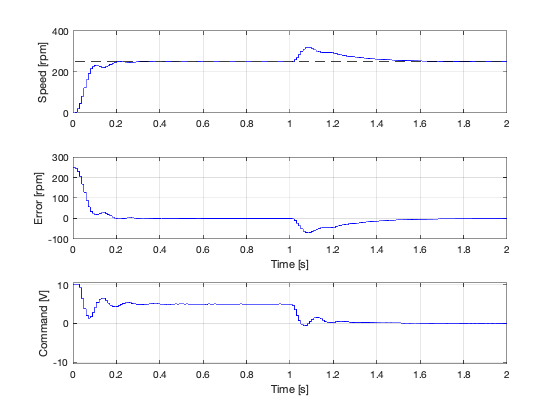

%   extract signas
t = simres.time;
w_meas = simres.signals(1).values(:,1);
w_ref = simres.signals(1).values(:,2);
e = simres.signals(2).values;
u1 = simres.signals(3).values;

%   plot results
figure;
subplot(3,1,1);
stairs(t, w_meas, 'b');
hold on;
stairs(t, w_ref, 'k--');
grid on;
ylabel('Speed [rpm]');

subplot(3,1,2);
stairs(t, e, 'b');
grid on;
ylabel('Error [rpm]');
xlabel('Time [s]');
ylim([-100, 300]);

subplot(3,1,3);
stairs(t, u1, 'b');
grid on;
ylim([-10.5, 10.5]);
ylabel('Command [V]');
xlabel('Time [s]');